# Model Accuracy

This script checks the accuracy of the four prediction model on a given real dataset.

## 🚀 Initialization

clc; clear all;

% Directory
par_dir = '../';

% Load data
filename = 'Atlanta_Shif_TypSum_RB_2004_TypOcc_TypBehav_NoTES_06162023_105632';
data = load([par_dir '/real_data/' filename '.mat']);

% Load model for estimation
model_name = 'wshp_power_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_sen_load_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_lat_load_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_airflow_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);


## 🧹 Preprocess

% Check and truncate excess data
if length(data.Measurements) > 1441
    data.Measurements = data.Measurements(1:1441,:);
    data.SupvCtrlSig = data.SupvCtrlSig(1:1441,:);
    data.SimData = data.SimData(1:1441,:);
    if iscell(data.SimData)
        for i = 1:length(data.SimData)
            temp(i,1) = data.SimData{i,1};
        end
        data.SimData = temp;
    end
end

% Process hardware data
hdata_name = fieldnames(data.HardwareData);
hdata = eval(['data.HardwareData.' hdata_name{1}]);
[hdata_sim,~] = hwdata_sent(hdata,data.Measurements);

% Extract data
time_step = [data.Measurements.Timestep]';
sim_zone_temp = [data.SimData.T_z]';
sim_zone_hr = [data.SimData.w_z]';
tstat_spt = [data.SimData.Tz_cspt]';
inlet_water_temp = hdata_sim.("Inlet Water Temp [°C]");
return_air_temp = [data.Measurements.T_z]';
return_air_hr = hdata_sim.("WSHP Avg Return HR [kg/kg]");
wshp_power = [data.Measurements.Power_HVAC]'/1000;
sen_load = hdata_sim.("Meas Sensible Load [kW]");
lat_load = hdata_sim.("Meas Latent Load [kW]");
air_cfm = hdata_sim.("WSHP Air Flowrate [cfm]");
sys_stat_full = [data.SupvCtrlSig.sys_status]';
sys_stat = sys_stat_full(:,2);
sup_temp = [data.Measurements.T_sup]';

% Calculate active setpoint
active_setpoint = tstat_spt + 1.5/1.8;

% Calculate the error
error = sim_zone_temp - active_setpoint;

% Calculate accumulated error
criteria_series = sys_stat;
reset_threshold = 0.5;
acc_error = accumulated_errors_1min(sim_zone_temp, active_setpoint, criteria_series, reset_threshold);

## Verify load data  

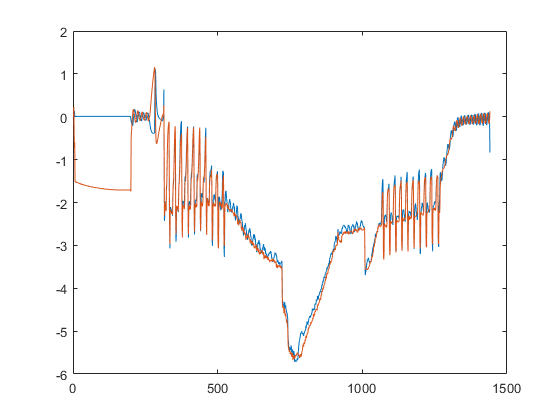

cpa = 1.006;
cpw = 1.86;
hwe = 2501;
air_kgs = air_cfm * 0.0283 * 1.225 / 60;
sen_load_cal = air_kgs .* (cpa + cpw .* sim_zone_hr) .* (sup_temp - sim_zone_temp);

figure;
plot(sen_load);
hold on
plot(sen_load_cal);
hold off

## 🔎 Check accuracy on real data (unseen)

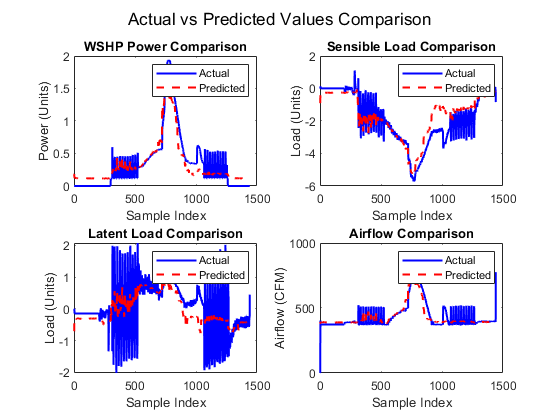

% Features
X = [error,  acc_error, inlet_water_temp, sim_zone_temp, sim_zone_hr];

% Actual
y1_act = wshp_power;
y2_act = sen_load;
y3_act = lat_load;
y4_act = air_cfm;

% Predict
y1_pred = predict(power_model,X);
y2_pred = predict(sen_load_model,X);
y3_pred = predict(lat_load_model,X);
y4_pred = predict(airflow_model,X);

% Create a new figure
figure;

% Subplot 1: wshp_power actual vs predicted
subplot(2,2,1); % This specifies a 2x2 grid, first position
plot(y1_act, 'b-', 'LineWidth', 1.5); hold on; % Actual values in blue
plot(y1_pred, 'r--', 'LineWidth', 1.5); hold off; % Predicted values in red dashed
title('WSHP Power Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Power (Units)');

% Subplot 2: sen_load actual vs predicted
subplot(2,2,2); % Second position
plot(y2_act, 'b-', 'LineWidth', 1.5); hold on;
plot(y2_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Sensible Load Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Load (Units)');

% Subplot 3: lat_load actual vs predicted
subplot(2,2,3); % Third position
plot(y3_act, 'b-', 'LineWidth', 1.5); hold on;
plot(y3_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Latent Load Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Load (Units)');

% Subplot 4: air_cfm actual vs predicted
subplot(2,2,4); % Fourth position
plot(y4_act, 'b-', 'LineWidth', 1.5); hold on;
plot(y4_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Airflow Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Airflow (CFM)');

% Adjust subplot layouts to avoid overlap
sgtitle('Actual vs Predicted Values Comparison'); % Super title for the entire figure